# Example: MHKiT-MATLAB Wave Module

The following example runs an application of the [MHHKiT wave module](https://mhkit-code-hub.github.io/MHKiT/source/mhkit-matlab/mhkit.wave.html) to 1) generate a capture length matrix, 2) calculate MAEP, and 3) plot the scatter diagrams.

## Generating Example Data 

For demonstration purposes, this example uses synthetic data generated from statistical distributions. The data includes significant wave height, peak period, power, and omnidirectional wave flux. In a real application, the user would provide these values. 

% generating an array of 1,000,000 values to represent significant wave
% height
Hm0 = normrnd(5.5,1.3,1000000,1);
% generating 1,000,000 values for peak period, assumng normal distribution
Te = normrnd(4.5,0.7,1000000,1);

% generating 1,000,000 random power values
Power = randi([40,200], 1000000,1); 

% generating 1,000,000 random omnidirectional wave flux values
J = randi([8,300], 1000000,1);

## Capture Length Matrices

The following operations create capture length matrices, as specified by the IEC/TS 62600-100. But first, we need to calculate capture length and define bin centers. The mean capture length matrix is printed below. Keep in mind that this data has been artificially generated, so it may not be representative of what a real-world scatter diagram would look like.

% calculating capture length with power and wave flux in vectors
L = capture_length(Power,J); 

% Need to set our Hm0 and Te bins for the capture length matrix
Hm0_bins = -0.5:0.5:max(fix(Hm0))+0.5; % Input is min, max, and n indecies for vector
Hm0_bins = Hm0_bins+0.25 ; 
Te_bins = 0:1:max(fix(Te));
Te_bins = Te_bins+0.5;

% Calculate the necessary capture length matrices for each statistic based
% on IEC/TS 62600-100
clmat.mean = capture_length_matrix(Hm0,Te,L,"mean",Hm0_bins,Te_bins);
clmat.std = capture_length_matrix(Hm0,Te,L,"std",Hm0_bins,Te_bins);
clmat.count = capture_length_matrix(Hm0,Te,L,"count",Hm0_bins,Te_bins);
clmat.min = capture_length_matrix(Hm0,Te,L,"min",Hm0_bins,Te_bins);
clmat.max = capture_length_matrix(Hm0,Te,L,"max",Hm0_bins,Te_bins);

% Calculate the frequency matrix for convenience 
clmat.freq = capture_length_matrix(Hm0,Te,L,"frequency",Hm0_bins,Te_bins);

Let's see what the data in the mean matrix looks like. Keep in mind that this data has been artificially generated, so it may not be representative of what a real-world scatter diagram would look like.

disp(clmat.mean.values)

       NaN       NaN       NaN    1.0080    1.4869       NaN       NaN       NaN       NaN
       NaN       NaN    0.4841    1.5516    1.8413    1.5821    0.2986       NaN       NaN
       NaN       NaN    0.2920    1.6859    1.1601    1.6711    1.0137       NaN       NaN
       NaN       NaN    0.7727    1.5493    1.7167    1.7178    1.5698       NaN       NaN
       NaN       NaN    1.6559    1.4591    1.5149    1.4314    1.1955       NaN       NaN
       NaN    0.9823    1.2649    1.5240    1.6065    1.5435    1.5874    1.4589       NaN
       NaN    2.3377    1.4140    1.4623    1.5046    1.4553    1.2991    1.6647       NaN
       NaN    0.6311    1.4417    1.4574    1.5147    1.5134    1.3223    2.4293       NaN
       NaN    0.9400    1.4096    1.4907    1.5002    1.5220    1.4551    1.3784       NaN
       NaN    2.3463    1.5166    1.4879    1.5141    1.4926    1.4729    2.9198    1.3356
       NaN    1.5832    1.5003    1.5149    1.5213    1.5139    1.4887    2.6026       NaN

## Power Matrices

As specified in IEC/TS 62600-100, the power matrix is generated from the capture length matrix and wave energy flux matrix, as shown below

% Create wave energy flux matrix using mean
jmat = wave_energy_flux_matrix(Hm0,Te,J,"mean",Hm0_bins,Te_bins);

% Create power matrix using mean
avg_power_mat = power_matrix(clmat.mean, jmat);

% Create power matrix using standard deviation
std_power_mat = power_matrix(clmat.std, jmat);

The `capture_length_matrix` function can also be used as an arbitrary scatter plot generator. To do this, simply pass a different array in the place of capture length (L). For example, while not specified by the IEC standards, if the user doesn't have the omnidirectional wave flux, the average power matrix could hypothetically be generated in the following manner:

avgpowmat_not_standard = capture_length_matrix(Hm0,Te,Power,'mean',Hm0_bins,Te_bins);

## MAEP

There are two ways to calculate mean annual energy production (MEAP). One is from capture length and wave energy flux matrices, the other is from time series data, as shown below.

% Calcaulte maep from timeseries
maep_timeseries = mean_annual_energy_production_timeseries(L,J)

maep_timeseries = 1.0519e+06

% Calcaulte maep from matrix
maep_matrix = mean_annual_energy_production_matrix(clmat.mean, jmat , clmat.freq)

maep_matrix = 2.0399e+06

## Graphics

The graphics function `plot_matrix` can be used to visualize results. It is important to note that the plotting function assumes the step size between bins to be linear.

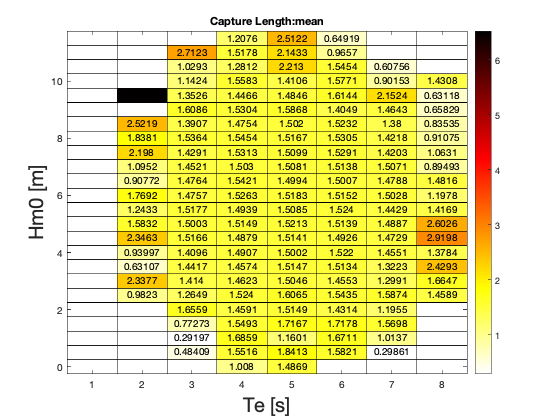

% Plot the capture length matrix
p1 = plot_matrix(clmat.mean,"Capture Length");